clusterCenters = 1×6 single 행 벡터
   93.7865  140.3885   93.4131  126.3431   87.5879  135.1655


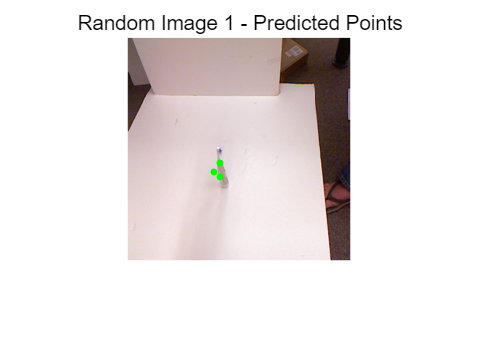

clusterCenters = 1×6 single 행 벡터
  110.6022  130.1560  109.6935  132.6697   95.8916  133.1584


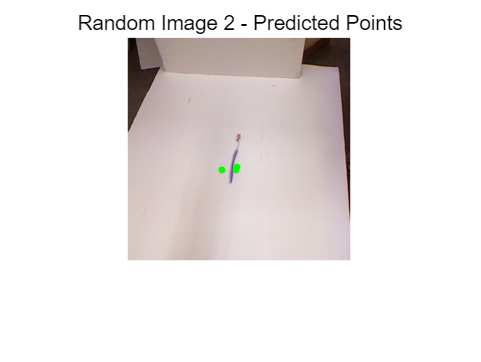

clusterCenters = 1×6 single 행 벡터
  111.5798  119.1911  113.8146  103.0058  110.8094  111.1255


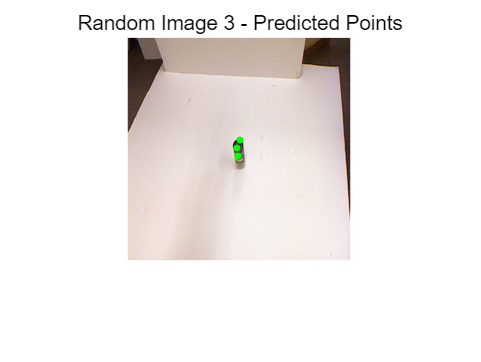

clusterCenters = 1×6 single 행 벡터
  118.5280  132.0073  106.0171  116.6776  111.5514  125.6616


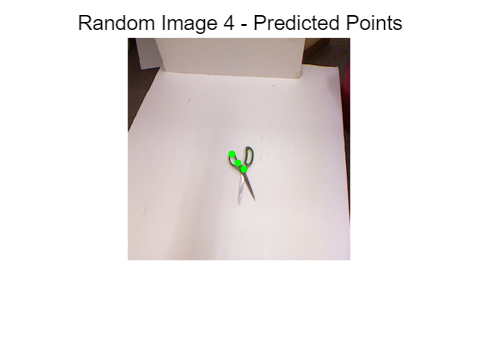

clusterCenters = 1×6 single 행 벡터
   91.4307  129.7314   83.7643  133.2639   84.3637  128.1518


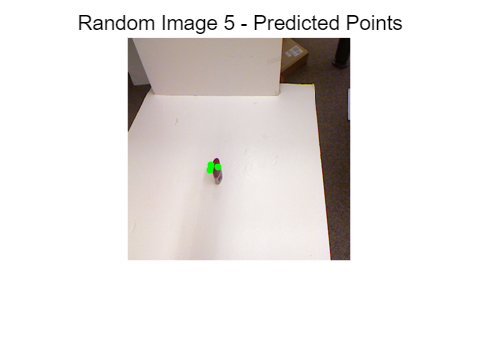

% 특정 폴더의 모든 PNG 파일 목록 가져오기
imageFolder = 'data'; % 이미지 폴더 경로를 지정하세요
imageFiles = dir(fullfile(imageFolder, '*.png'));

% PNG 파일 개수 확인
numImages = length(imageFiles);

% 무작위로 5개 파일 선택 (파일 수가 5개 미만이면 모든 파일 선택)
numRandomImages = min(5, numImages);
randomIdx = randperm(numImages, numRandomImages);

loadedData = load("GraspPoint5.mat");
net = loadedData.net;

for i = 1:numRandomImages
    % 선택된 이미지 파일 불러오기
    imageFile = fullfile(imageFolder, imageFiles(randomIdx(i)).name);
    testImage = imread(imageFile);
    resizedImage = imresize(testImage, [224 224]); 
    
    % 예측된 8개의 점 좌표 (예시로 네트워크에서 예측된 값을 가져옴)
    predictedPoints2 = predict(net, resizedImage); 
    clusterCenters = calculateClusterCenters(predictedPoints2(1,:))
    % 결과 시각화
    figure;
    imshow(resizedImage); % 크기 조정된 이미지를 표시
    hold on;
    % 예측된 모든 점을 빨간색으로 표시 (참고용)
    for j = 1:3
        plot( clusterCenters(2*j-1),  clusterCenters(2*j), 'go', 'MarkerSize', 1, 'LineWidth', 2);
    end
     
    hold off;
    title(sprintf('Random Image %d - Predicted Points', i));
end

function clusterCenters = calculateClusterCenters(points)
    % points는 8개의 (x, y) 좌표로 이루어진 1x16 배열입니다.
    pointsMatrix = reshape(points, [2, 8])';  % 8개의 좌표를 [x, y] 형태로 변환
    [~, C] = kmeans(pointsMatrix, 3);  % 3개의 클러스터 중심 계산
    clusterCenters = reshape(C', 1, []);  % 클러스터 중심을 1x6 형태로 변환
end